load("dataset.mat")

var_Q = [];
for i = 10:10:N
    var_Q = [var_Q;var(Q(1:i))];
end    

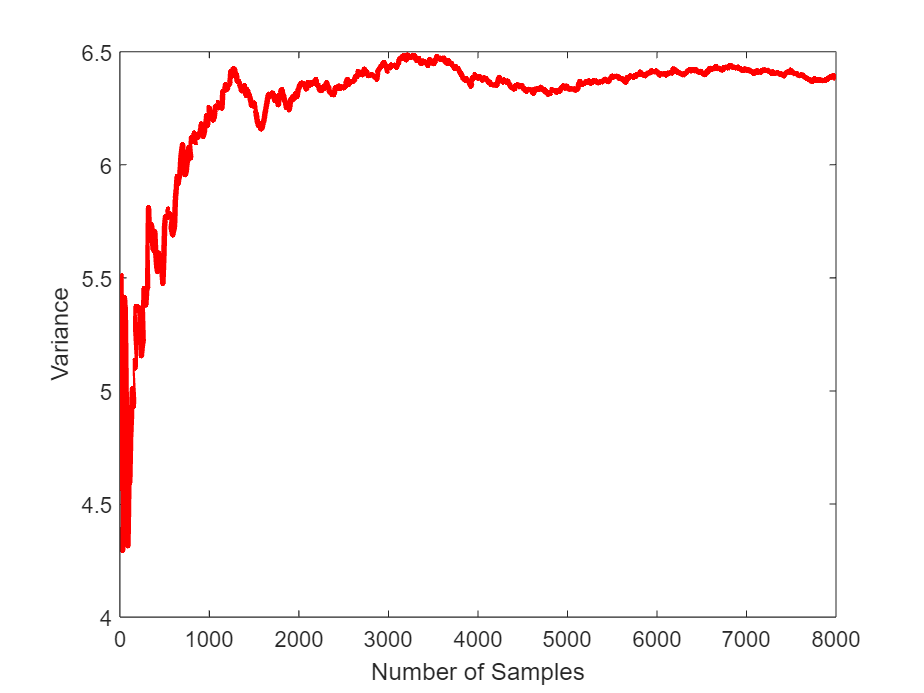

sample_s = 10:10:N; %creates a row vector
plot(sample_s, var_Q,LineWidth=2.5,Color='red')  
xlabel('Number of Samples'); 
ylabel('Variance'); 

var_Q_meas=[];
for i = 10:10:N
    var_Q_meas=[var_Q_meas;var(Q_meas(1:i))];
end     

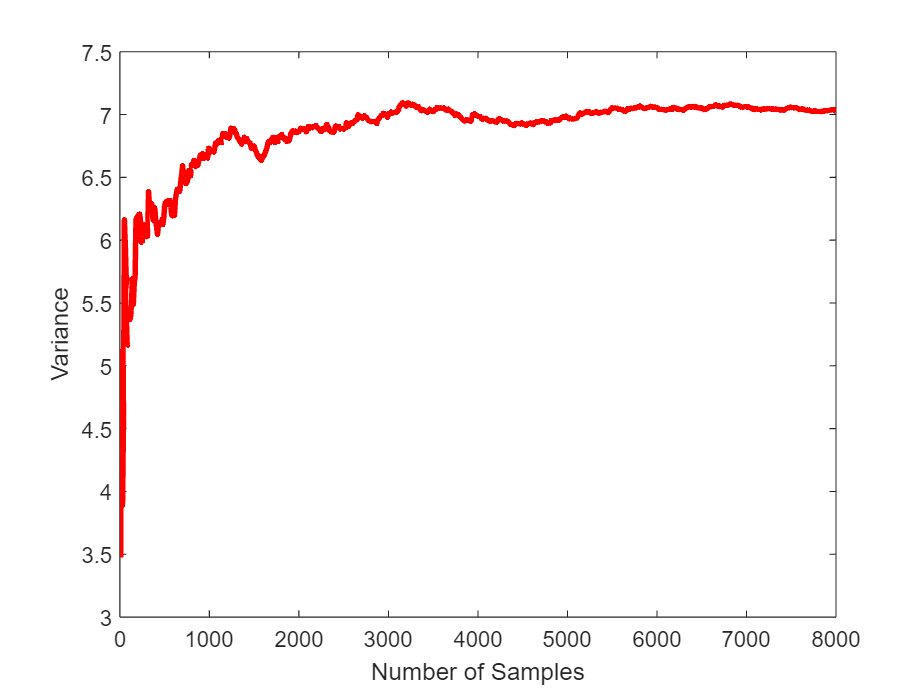

sample_s = 10:10:N; %creates a row vector
plot(sample_s,var_Q_meas, Linewidth = 2.5 , Color='red')  
xlabel('Number of Samples'); 
ylabel('Variance'); 

var_Q_meas2=[];
for i = 10:10:N
    var_Q_meas2=[var_Q_meas2;var(Q_meas2(1:i))];
end     

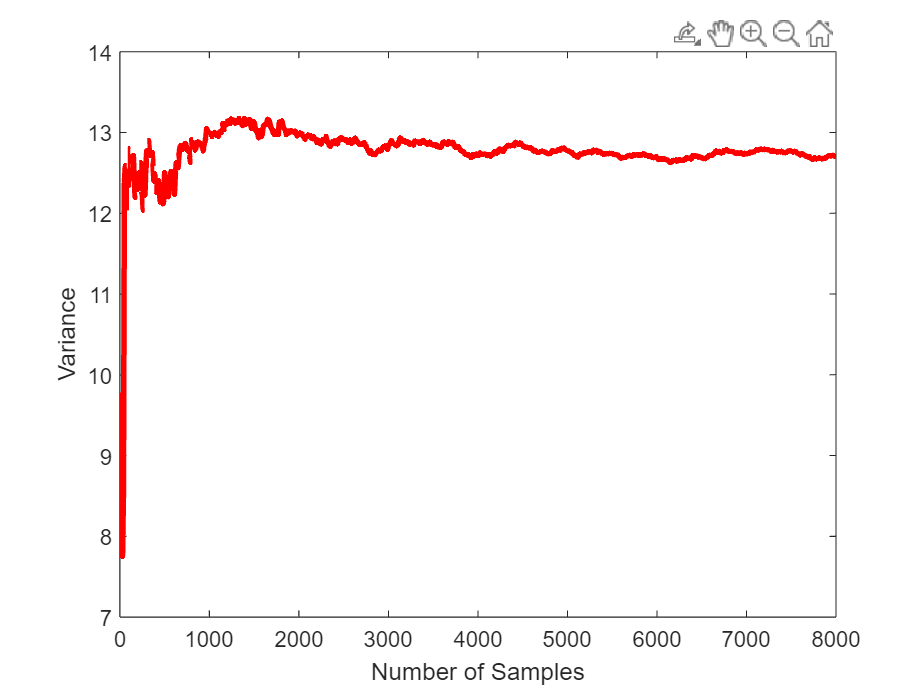

sample_s = 10:10:N; %creates a row vector
plot(sample_s,var_Q_meas2, Linewidth = 2.5 , Color='red')  
xlabel('Number of Samples'); 
ylabel('Variance'); 

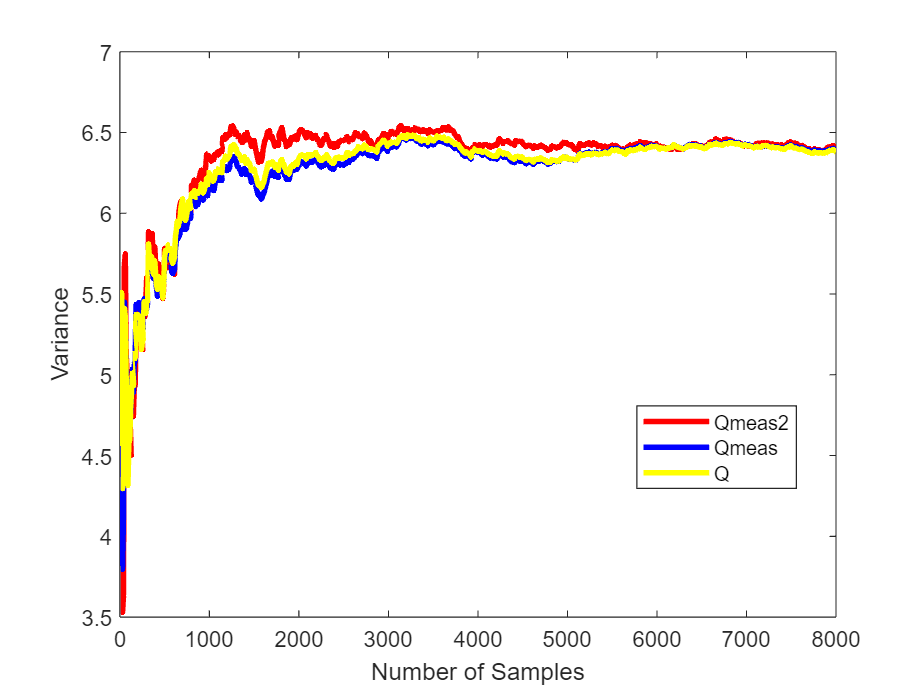

var_TQ_meas2 = [];
var_TQ_meas = [];
var_TQ = [];
for i = 10:10:N
    a = cov(Tf(1:i),Q_meas2(1:i));
    var_TQ_meas2 = [var_TQ_meas2;a(2,1)];
    b = cov(Tf(1:i),Q_meas(1:i));
    var_TQ_meas = [var_TQ_meas;b(2,1)];
    c = cov(Tf(1:i),Q(1:i));
    var_TQ = [var_TQ;c(2,1)];
end

sample_s = 10:10:N; %creates a row vector
plot(sample_s,var_TQ_meas2, Linewidth = 2.5 , Color='red')
hold on;
plot(sample_s,var_TQ_meas, Linewidth = 2.5 , Color='blue') 
plot(sample_s,var_TQ, Linewidth = 2.5 , Color='yellow')  
hold off;
xlabel('Number of Samples'); 
ylabel('Variance'); 
legend('Qmeas2', 'Qmeas', 'Q', Location='best');

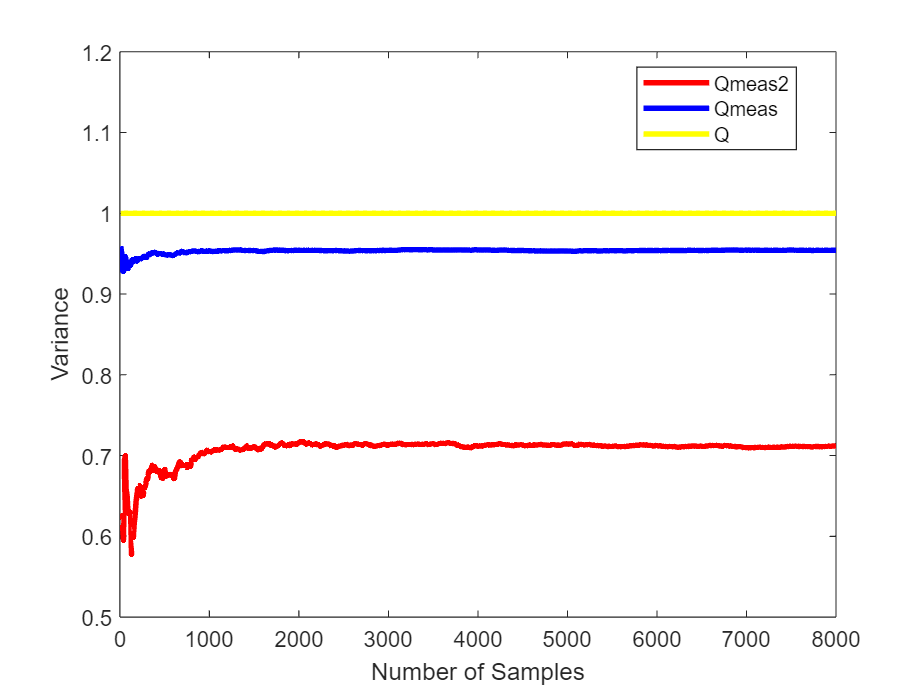

var_TQ_meas2 = [];
var_TQ_meas = [];
var_TQ = [];
for i = 10:10:N
    a = corr(Tf(1:i),Q_meas2(1:i));
    var_TQ_meas2 = [var_TQ_meas2;a];
    b = corr(Tf(1:i),Q_meas(1:i));
    var_TQ_meas = [var_TQ_meas;b];
    c = corr(Tf(1:i),Q(1:i));
    var_TQ = [var_TQ;c];
end

sample_s = 10:10:N; %creates a row vector
plot(sample_s,var_TQ_meas2, Linewidth = 2.5 , Color='red')
hold on;
plot(sample_s,var_TQ_meas, Linewidth = 2.5 , Color='blue') 
plot(sample_s,var_TQ, Linewidth = 2.5 , Color='yellow')  
hold off;
xlabel('Number of Samples'); 
ylabel('Variance'); 
ylim([0.5,1.2]);
legend('Qmeas2', 'Qmeas', 'Q', Location='best');

SNR_Q_meas2 = var(Q(:))./var((Q_meas2(:)-Q(:)))

SNR_Q_meas2 = 1.0174

SNR_Q_meas = var(Q)./var((Q_meas-Q))

SNR_Q_meas = 10.1286